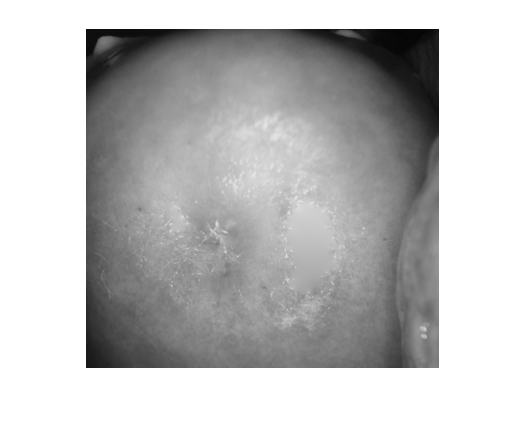

% clc,clear all

img=imread('W100.tif');
% img=imresize(img,0.25);
img_gray=rgb2gray(img);
imshow(img_gray)

% hist_eq=histeq(img_gray);
% r=img(:,:,1);
% G=img(:,:,2);
% B=img(:,:,3);
% imshowpair(hist_eq,img_gray,'montage')
% imshowpair(r,B,'diff')


%read and display input image
n_dir=4;
offset=[0 1;0 5;0 10;0 15;...
    -1 1; -5 5;-10 10;-15 15;...
    -1 0;-5 0;-10 0;-15 0;...
    -1 -1;-5 -5;-10 -10;-15 -15;];% offset of four directions 
%and 4 distances for each direction. i.e [D,0],[-D,D],[-D,0],[-D,-D];
[glcms, SI]=graycomatrix(img_gray,'NumLevels',256,'Offset',offset);% Returns glcm and scaled 
%image used to calculate glcm
stats=graycoprops(glcms)

stats = struct with fields:
       Contrast: [9.4406 66.3714 153.3546 255.9718 16.0809 103.6663 254.6552 444.1801 9.5398 66.8597 145.1406 235.3669 16.0859 100.7847 223.4971 352.7273]
    Correlation: [0.9978 0.9847 0.9641 0.9392 0.9963 0.9756 0.9381 0.8893 0.9978 0.9849 0.9673 0.9467 0.9964 0.9771 0.9481 0.9156]
         Energy: [9.0837e-04 3.0994e-04 2.0956e-04 1.6668e-04 7.0572e-04 2.5857e-04 1.7434e-04 1.3982e-04 0.0010 3.4732e-04 2.3459e-04 1.8376e-04 7.1860e-04 2.6974e-04 1.8574e-04 1.5152e-04]
    Homogeneity: [0.5074 0.2620 0.1881 0.1518 0.4381 0.2232 0.1571 0.1265 0.5229 0.2758 0.2037 0.1656 0.4472 0.2394 0.1725 0.1398]


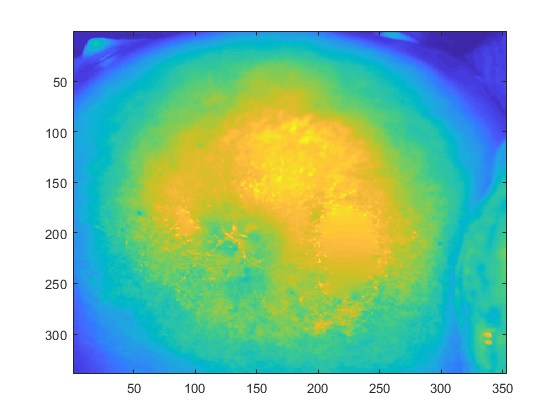



con=reshape(stats.Contrast,[],n_dir);%intensity contrast as a function of pixel distance shows definition and degree of texture depth
cor=reshape(stats.Correlation,[],n_dir);%reflects similarity on a direction of image texture and is the linear correlation
Ener=reshape(stats.Energy,[],n_dir);
hom=reshape(stats.Homogeneity,[],n_dir);

% mean_con=mean(con,2);
% mean_cor=mean(cor,2);
% mean_Ener=mean(Ener,2);
% mean_hom=mean(hom,2);
% figure;imagesc(SI)
% all_stats=[mean_con;mean_cor;mean_Ener;mean_hom]

mean_con=mean(stats.Contrast);
mean_cor=mean(stats.Correlation);
mean_Ener=mean(stats.Energy);
mean_hom=mean(stats.Homogeneity);
figure;imagesc(SI)

all_stats=[mean_con,mean_cor,mean_Ener,mean_hom]

all_stats =   153.3577
    0.9637
    0.0004
    0.2638


save('haralicks.mat','all_stats')
% t1=stuct2array(stats)